## Read excel files into a cell array with xlsread()

[m,txt,raw] = xlsread('patientdata.xlsx');



m

m = 	1.0e+04 *

    0.0064    0.0001    0.1638    0.1659    0.1624    0.1704    0.1737    0.1688
    0.0042    0.0001    0.1057    0.1083    0.0982    0.1027    0.0975    0.1186
    0.0045    0.0001    5.2326    5.2278    5.2417    5.2296    5.2479    5.2371
    0.0036    0.0001    0.1788    0.1787    0.1818    0.1909    0.1922    0.1775
    0.0038    0.0001    0.3565    0.3593    0.3456    0.3550    0.3529    0.3433
    0.0062    0.0001    1.2457    1.2119    1.2131    1.2079    1.2076    1.2200
    0.0045    0.0001    1.3321    1.3004    1.3034    1.2940    1.2968    1.2937
    0.0051    0.0001    1.7041    1.6627    1.6656    1.6606    1.6591    1.6610
    0.0063    0.0001    0.1008    0.0657    0.0716    0.0648    0.0639    0.0700
    0.0040    0.0001    0.9337    0.9001    0.8929    0.8909    0.9008    0.8919


txt

txt = 1×8 cell array
    {'age'}    {'drugregimen'}    {'viralload0'}    {'viralload1'}    {'viralload2'}    {'viralload3'}    {'viralload4'}    {'viralload5'}


raw

fields = raw(1,:);
fields

fields = 1×8 cell array
    {'age'}    {'drugregimen'}    {'viralload0'}    {'viralload1'}    {'viralload2'}    {'viralload3'}    {'viralload4'}    {'viralload5'}


## Use logical index arrary to select certain data. I = m(:, groupcol) == 1; ageofgroup1=m(I,agecol). 

I=m(:,2)==1

I = 500×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


ageofgroup1=m(I,1)

ageofgroup1 =     64
    42
    45
    36
    38
    62
    45
    51
    63
    40


aveageofgroup1=mean(ageofgroup1,1)

aveageofgroup1 = 40.7364

stdageofgroup1=std(ageofgroup1,1)

stdageofgroup1 = 13.9498

aveageofgroup1=mean(ageofgroup1,2)

aveageofgroup1 =     64
    42
    45
    36
    38
    62
    45
    51
    63
    40


## MATLAB function  any();

viraload=m(:,3:end) % assign the all the values (viralloads) from column 3 to colomn 6 to a variable

viraload = 	1.0e+04 *

    0.1638    0.1659    0.1624    0.1704    0.1737    0.1688
    0.1057    0.1083    0.0982    0.1027    0.0975    0.1186
    5.2326    5.2278    5.2417    5.2296    5.2479    5.2371
    0.1788    0.1787    0.1818    0.1909    0.1922    0.1775
    0.3565    0.3593    0.3456    0.3550    0.3529    0.3433
    1.2457    1.2119    1.2131    1.2079    1.2076    1.2200
    1.3321    1.3004    1.3034    1.2940    1.2968    1.2937
    1.7041    1.6627    1.6656    1.6606    1.6591    1.6610
    0.1008    0.0657    0.0716    0.0648    0.0639    0.0700
    0.9337    0.9001    0.8929    0.8909    0.9008    0.8919


cured=any(viraload<=48,2) % across a single row

cured = 500×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


curedcol=any(viraload<=48,1) % across a single column

curedcol = 1×6 logical array
   0   1   1   1   1   1


curedofgroup1=cured(I)

curedofgroup1 = 129×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


## MATLAB function diff()

c=diff(viraload,1,2)

c = 	1.0e+03 *

    0.0215   -0.0352    0.0794    0.0338   -0.0493
    0.0263   -0.1014    0.0457   -0.0519    0.2106
   -0.0476    0.1391   -0.1219    0.1834   -0.1076
   -0.0010    0.0309    0.0906    0.0134   -0.1475
    0.0275   -0.1371    0.0948   -0.0212   -0.0966
   -0.3379    0.0114   -0.0514   -0.0026    0.1233
   -0.3177    0.0305   -0.0936    0.0276   -0.0307
   -0.4145    0.0293   -0.0506   -0.0142    0.0186
   -0.3510    0.0586   -0.0673   -0.0093    0.0609
   -0.3358   -0.0719   -0.0200    0.0992   -0.0889


## PLOT bar(), errobar()

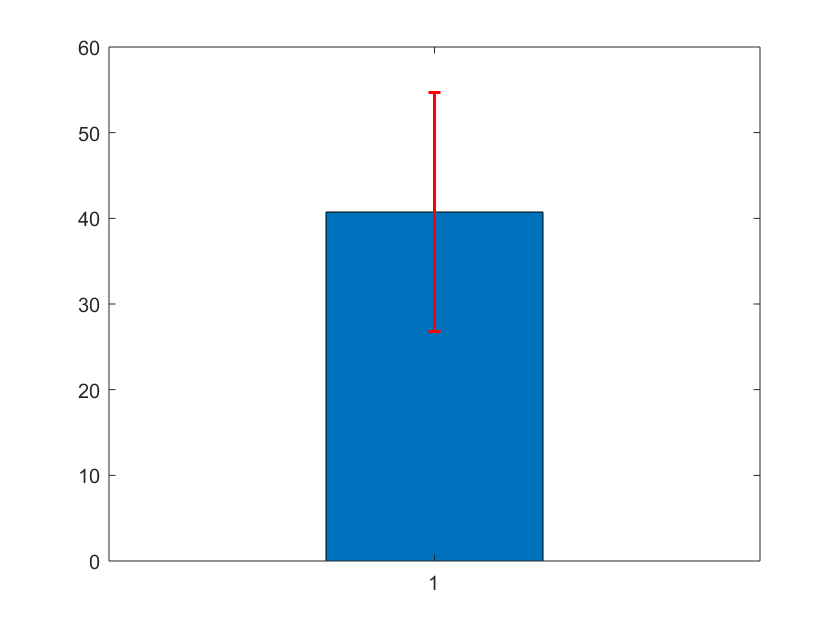

figure
bar(aveageofgroup1);
hold on;
errorbar(aveageofgroup1, stdageofgroup1, 'r', 'LineWidth',1.5, 'LineStyle','none' );

## PLOT hist()

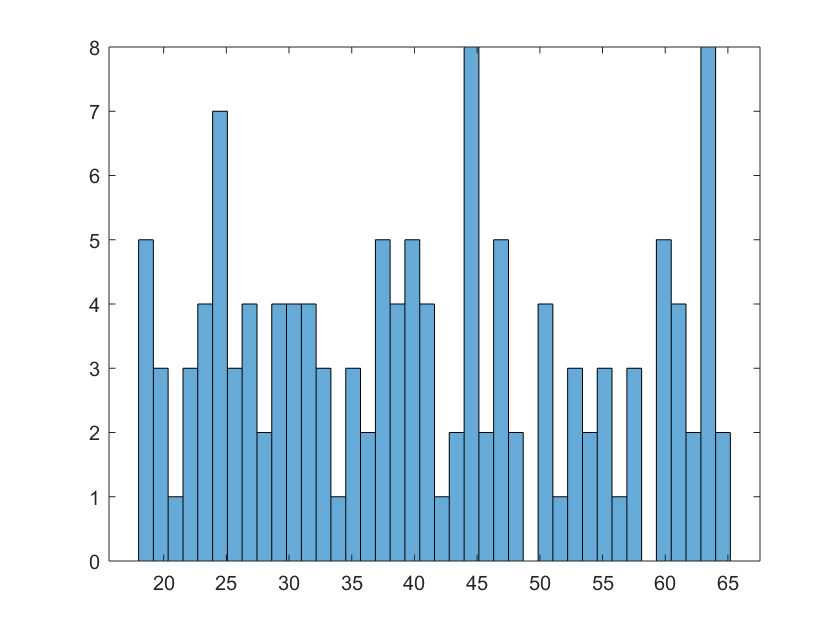


figure
histogram(ageofgroup1, 40)